# Final assignment

## One: Exercise for one-page report

### Question one: 

- Gradient and Hessian are shown below

clear all;
syms x_1 x_2 
fun = x_1^4 - 2*x_2*x_1^2 + x_2^2 + x_1^2 - 2*x_1 + 5

$$fun = {x_{1}}^{4}-2\,{x_{1}}^{2}\,x_{2}+{x_{1}}^{2}-2\,x_{1}+{x_{2}}^{2}+5$$

grd = jacobian(fun,[x_1 x_2])

$$grd = \left(\begin{array}{cc} 2\,x_{1}-4\,x_{1}\,x_{2}+4\,{x_{1}}^{3}-2 & 2\,x_{2}-2\,{x_{1}}^{2} \end{array}\right)$$

hes = jacobian(grd,[x_1 x_2])

$$hes = \left(\begin{array}{cc} 12\,{x_{1}}^{2}-4\,x_{2}+2 & -4\,x_{1}\\ -4\,x_{1} & 2 \end{array}\right)$$

Hessian = matlabFunction(hes);
evls = eig(Hessian(0,0.5))

evls =      0
     2


### Question two:

- For this polynomial function, continuity of gradient is gaurantteed everywhere.

- The optimal value has to locate at points where gradients are zero.

- The function value can go positive infinity such that [1,1] can't be a maximizer.

result = solve([grd(1)==0, grd(2)==0],[x_1,x_2])

result = struct with fields:
    x_1: [1×1 sym]
    x_2: [1×1 sym]


result.x_1

$$ans = 1$$

result.x_2

$$ans = 1$$

### Question three:

- Contour plot is displayed below

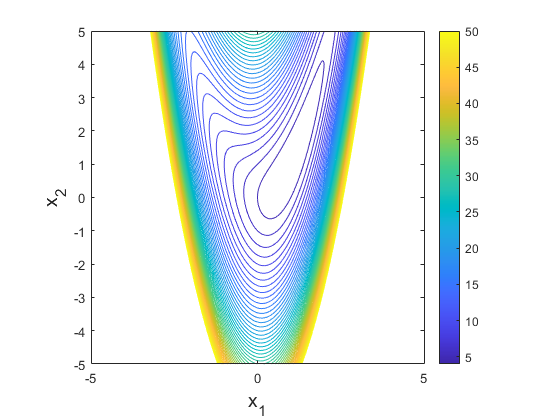

v = [3:50];
funObj = matlabFunction(fun);
x =  -5:0.05:5;
y =  -5:0.05:5;
[X,Y] = meshgrid(x,y);
figure
[C,h] = contour(X,Y,funObj(X,Y),v);
colorbar, axis image,
xlabel('x_1','fontsize',14)
ylabel('x_2','fontsize',14)

### Question four:

- See function definition

[fm, dfm, d2fm] = myFun([1,1])

fm = 4

dfm =      0
     0


d2fm =     10    -4
    -4     2


### Question five:

- Steepest descent method with  line search

% Starting point
x0 = [1;4];
% Running
[x_sl,stat_sl] = steepestdescent_backtracking(1,0.5,0.1,@myFun,x0,200,1e-6)

'steepestdescent_backtracking' is not found in the current folder or on the MATLAB path, but exists in:
    F:\Gathering-of-lecture-exercises\02610\Week 13\script\week13-final assignment

Change the MATLAB current folder or add its folder to the MATLAB path.

stat_sl.X(:,1:9)
% First eight iterates
figure
[C,h] = contour(X,Y,funObj(X,Y),v);
hold on
plot(stat_sl.X(1,1:8),stat_sl.X(2,1:8),'r-*')
hold on
scatter([1],[1],'green','filled')
colorbar, axis image,
xlabel('x_1','fontsize',14)
ylabel('x_2','fontsize',14)
title('steepest descent method with line search')

% Semilogy plots
ek = stat_sl.X - [1;1];
figure
semilogy(0:stat_sl.iter,sqrt(ek(1,:).^2 + ek(2,:).^2),'r-o')
hold on
semilogy(0:stat_sl.iter,stat_sl.F,'g-x')
hold on
semilogy(0:stat_sl.iter,stat_sl.dF,'b-*')
grid on
hold off
legend('||e_k||_2','f(x_k)','|df(x_k)|_2')
title('steepest descent method with line search')

- Newton's method

% Running
[x_n,stat_n] = newton_fixedStep(0.8,@myFun,[1;4],200,1e-6)

x_n =     1.0000
    1.0000


stat_n = struct with fields:
    converged: 1
         nfun: 12
         iter: 11
            X: [2×12 double]
            F: [13 4.3600 4.0144 4.0006 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000]
           dF: [13.4164 2.6833 0.5367 0.1073 0.0215 0.0043 8.5865e-04 1.7173e-04 3.4346e-05 6.8692e-06 1.3738e-06 2.7477e-07]


stat_n.X(:,1:9)

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    4.0000    1.6000    1.1200    1.0240    1.0048    1.0010    1.0002    1.0000    1.0000



% Checek eigenvalues in these iterations
for i = 1:9
    stat_n.X(:,i)
    evls = eig(Hessian(x(1),x(2)))
end

ans =      1
     4


evls =     0.7541
  323.0459


ans =     1.0000
    1.6000


evls =     0.7541
  323.0459


ans =     1.0000
    1.1200


evls =     0.7541
  323.0459


ans =     1.0000
    1.0240


evls =     0.7541
  323.0459


ans =     1.0000
    1.0048


evls =     0.7541
  323.0459


ans =     1.0000
    1.0010


evls =     0.7541
  323.0459


ans =     1.0000
    1.0002


evls =     0.7541
  323.0459


ans =     1.0000
    1.0000


evls =     0.7541
  323.0459


ans =     1.0000
    1.0000


evls =     0.7541
  323.0459


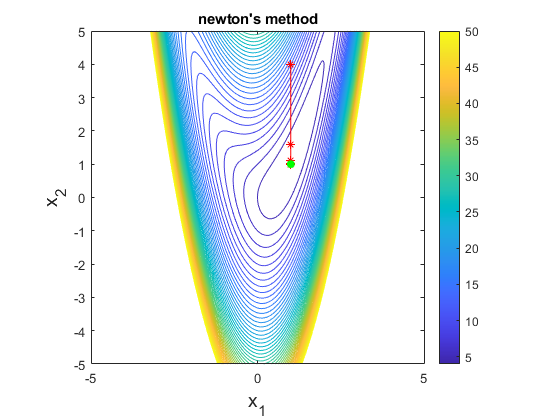


% First eight iterates
figure
[C,h] = contour(X,Y,funObj(X,Y),v);
hold on
plot(stat_n.X(1,1:8),stat_n.X(2,1:8),'r-*')
hold on
scatter([1],[1],'green','filled')
colorbar, axis image,
xlabel('x_1','fontsize',14)
ylabel('x_2','fontsize',14)
title("newton's method")

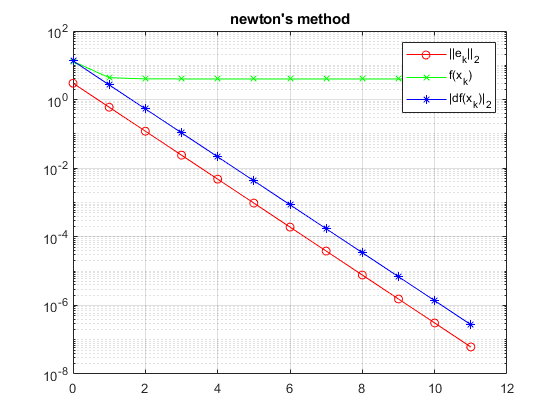


% Semilogy plots
ek = stat_n.X - [1;1];
figure
semilogy(0:stat_n.iter,sqrt(ek(1,:).^2 + ek(2,:).^2),'r-o')
hold on
semilogy(0:stat_n.iter,stat_n.F,'g-x')
hold on
semilogy(0:stat_n.iter,stat_n.dF,'b-*')
grid on
hold off
legend('||e_k||_2','f(x_k)','|df(x_k)|_2')
title("newton's method")

- BFGS method with line search

% Running
[x_bfgs,stat_bfgs] =  BFGSmethod_line(1,0.5,0.1,@myFun,x0, eye(2),200,1e-6)

x_bfgs =     1.0000
    1.0000


stat_bfgs = struct with fields:
    converged: 1
         nfun: 21
         iter: 20
            X: [2×21 double]
            F: [13 4.8789 4.7465 4.2395 4.0012 4.0010 4.0004 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000]
           dF: [13.4164 2.6846 0.4572 1.9469 0.0583 0.0534 0.0723 0.0089 0.0069 0.0030 2.4676e-04 6.4553e-05 1.8125e-04 5.3399e-05 2.9283e-05 5.4178e-05 7.1130e-06 1.5064e-05 8.9650e-06 1.4220e-06 4.3667e-07]
        Alpha: [1 0.0625 0.0313 1 0.0313 0.0313 0.0313 0.0078 0.0078 0.0039 0.0020 9.7656e-04 0.0039 4.8828e-04 4.8828e-04 9.7656e-04 1.2207e-04 2.4414e-04 6.1035e-05 3.0518e-05 3.0518e-05]


stat_bfgs.X(:,1:9)

ans =     1.0000    1.7500    1.8332    1.4584    0.9656    0.9759    0.9837    0.9978    0.9983
    4.0000    3.6250    3.5892    1.9556    0.9296    0.9315    0.9770    0.9927    0.9974


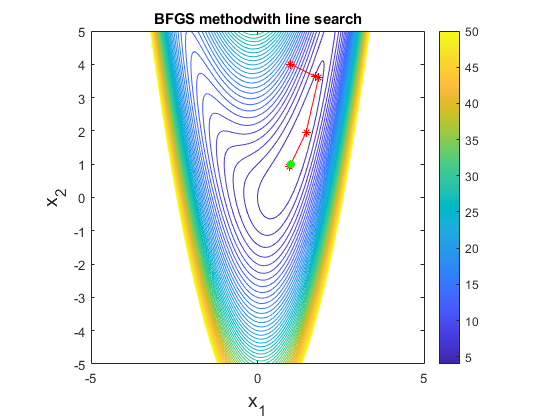

% First eight iterates
figure
[C,h] = contour(X,Y,funObj(X,Y),v);
hold on
plot(stat_bfgs.X(1,1:8),stat_bfgs.X(2,1:8),'r-*')
hold on
scatter([1],[1],'green','filled')
colorbar, axis image,
xlabel('x_1','fontsize',14)
ylabel('x_2','fontsize',14)
title("BFGS methodwith line search")

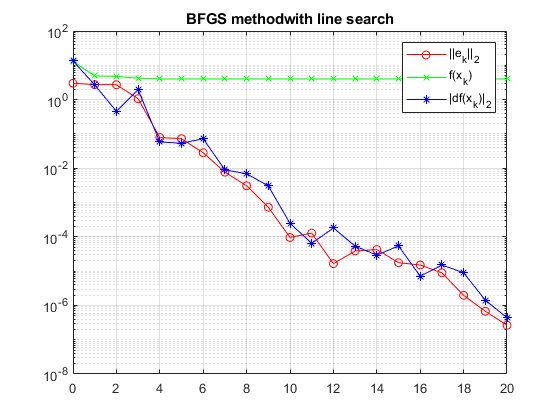


% Semilogy plots
ek = stat_bfgs.X - [1;1];
figure
semilogy(0:stat_bfgs.iter,sqrt(ek(1,:).^2 + ek(2,:).^2),'r-o')
hold on
semilogy(0:stat_bfgs.iter,stat_bfgs.F,'g-x')
hold on
semilogy(0:stat_bfgs.iter,stat_bfgs.dF,'b-*')
grid on
hold off
legend('||e_k||_2','f(x_k)','|df(x_k)|_2')
title("BFGS methodwith line search")

- Coordinate search

% Running
[x_c,stat_c] = coordinate(@myFun, x0, 1, 200, 1e-6)

x_c =     1.0000
    1.0000


stat_c = struct with fields:
    converged: 1
         nfun: 1
         iter: 147
            X: [2×148 double]
            F: [1×148 double]


stat_c.X(:,1:9)

ans =     1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    1.9375    1.9375    1.9375
    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    3.9375    3.8750


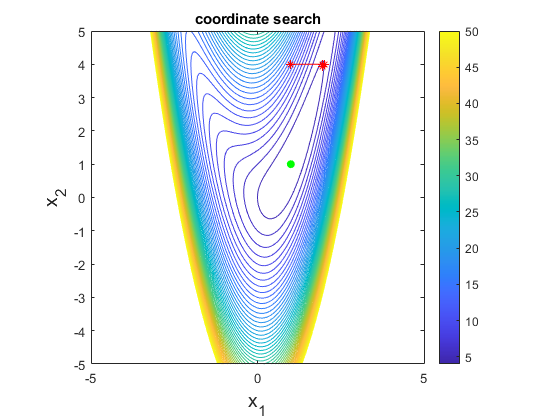

% First eight iterates
figure
[C,h] = contour(X,Y,funObj(X,Y),v);
hold on
plot(stat_c.X(1,1:8),stat_c.X(2,1:8),'r-*')
hold on
scatter([1],[1],'green','filled')
colorbar, axis image,
xlabel('x_1','fontsize',14)
ylabel('x_2','fontsize',14)
title("coordinate search")

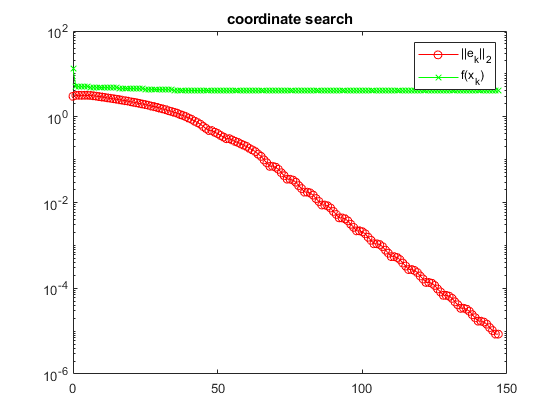


% Semilogy plots
ek = stat_c.X - [1;1];
figure
semilogy(0:stat_c.iter,sqrt(ek(1,:).^2 + ek(2,:).^2),'r-o')
hold on
semilogy(0:stat_c.iter,stat_c.F,'g-x')
hold off
legend('||e_k||_2','f(x_k)')
title("coordinate search")

- Nonlinear Conjugate gradient method with line search

[x_cb,stat_cb] = conjugate_backtracking(1,0.5,0.1,@myFun,x0,200,1e-6)

x_cb =     1.0000
    1.0000


stat_cb = struct with fields:
    converged: 1
         nfun: 32
         iter: 31
            X: [2×32 double]
            F: [13 4.8789 4.7761 4.7397 4.5261 4.2701 4.2701 4.1673 4.1584 4.0994 4.0994 4.0478 4.0149 4.0130 4.0025 4.0006 4.0003 4.0001 4.0001 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000 4.0000]
           dF: [1×32 double]
        Alpha: [1 0.0625 0.2500 0.0625 1 0.5000 2.2204e-16 0.2500 0.1250 0.2500 3.5527e-15 0.1250 1 0.5000 0.5000 0.2500 0.2500 0.1250 0.2500 0.1250 0.5000 0.1250 0.2500 0.1250 7.6294e-06 0.1250 1.5259e-05 0.1250 1.5259e-05 0.1250 3.0518e-05 0.1250]


stat_cb.X(:,1:9)

ans =     1.0000    1.7500    1.8795    1.8167    1.7245    0.4803    0.4803    0.7437    0.8154
    4.0000    3.6250    3.5837    3.5699    2.9390    0.2380    0.2380    0.2343    0.3123


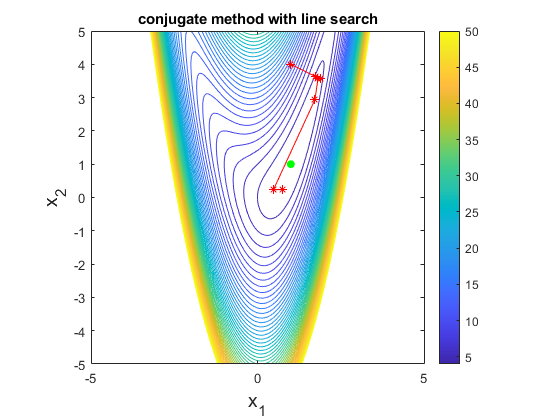

% First eight iterates
figure
[C,h] = contour(X,Y,funObj(X,Y),v);
hold on
plot(stat_cb.X(1,1:8),stat_cb.X(2,1:8),'r-*')
hold on
scatter([1],[1],'green','filled')
colorbar, axis image,
xlabel('x_1','fontsize',14)
ylabel('x_2','fontsize',14)
title("conjugate method with line search")

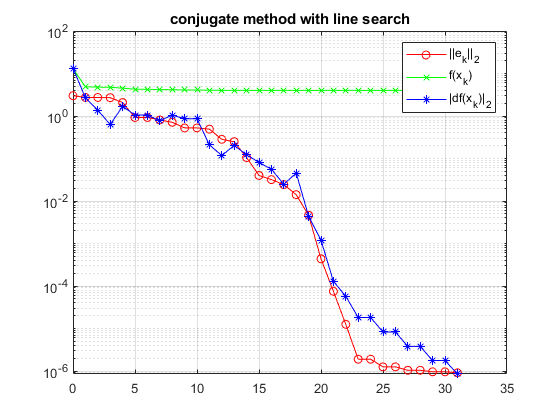


% Semilogy plots
ek = stat_cb.X - [1;1];
figure
semilogy(0:stat_cb.iter,sqrt(ek(1,:).^2 + ek(2,:).^2),'r-o')
hold on
semilogy(0:stat_cb.iter,stat_cb.F,'g-x')
hold on
semilogy(0:stat_cb.iter,stat_cb.dF,'b-*')
grid on
hold off
legend('||e_k||_2','f(x_k)','|df(x_k)|_2')
title("conjugate method with line search")

### Report: to finish

## Two: Convergence of CG method

### Question one:

- Condition numebrs are shown below, clearly as tau increases, condition number also increases.

- At tau = 0.3, the smallest eigenvalue is negative such that it is no longer positive-definite.

clear all;
taus = [0.01, 0.05, 0.09, 0.3];
for i = 1:4
    disp('tau:')
    tau = taus(i)
    A = genA(tau);
    disp('The condition number is:')
    cdn = condest(A)
    disp('The smallest eigenvalue is:')
    evls = eigs(A,1,'sm')
    evls = eigs(A,500)
    disp('Size of A is:')
    shape = size(A)
end

tau:


tau = 0.0100

The condition number is:


cdn = 1.2103

The smallest eigenvalue is:


evls = 0.9622

evls =     1.0372
    1.0365
    1.0360
    1.0356
    1.0349
    1.0345
    1.0344
    1.0338
    1.0335
    1.0333


Size of A is:


shape =    500   500


tau:


tau = 0.0500

The condition number is:


cdn = 9.7544

The smallest eigenvalue is:


evls = 0.5886

evls =     1.4034
    1.3983
    1.3930
    1.3900
    1.3844
    1.3787
    1.3769
    1.3745
    1.3713
    1.3680


Size of A is:


shape =    500   500


tau:


tau = 0.0900

The condition number is:


cdn = 353.6692

The smallest eigenvalue is:


evls = 0.0519

evls =     1.9674
    1.9421
    1.9290
    1.9166
    1.8955
    1.8922
    1.8895
    1.8754
    1.8736
    1.8673


Size of A is:


shape =    500   500


tau:


tau = 0.3000

The condition number is:


cdn = 2.4620e+04

The smallest eigenvalue is:


evls = -0.0046

evls =     6.2291
    6.1499
    6.0841
    6.0611
    6.0147
    5.8978
    5.8846
    5.8373
    5.8149
    5.7416


Size of A is:


shape =    500   500


### Question two:

- The convergence curves are shown below

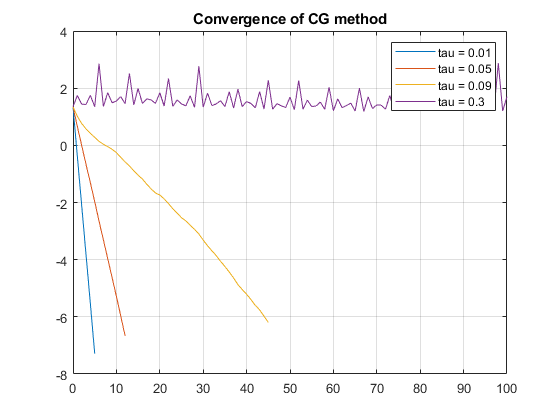

b = ones(500,1); 
x0 = zeros(500,1);
figure
for i = 1:4
    tau = taus(i);
    A = genA(tau);
    [x,stat]=cgm(A,b,x0);
    plot(0:stat.iter, log10(stat.resd))
    hold on
end
hold off
grid on
legend('tau = 0.01','tau = 0.05','tau = 0.09', 'tau = 0.3')
title('Convergence of CG method')

### Question three:

- the cg method is based on the assumption that the matrix should be positive-definite but obviously when tau = 0.3, it is no more positive definite. Then the algorithm will not be valid.

## Three: Necessary condition

### Question one:

- Write down the KKT conditions for this problem

- the objective function and constraint are differentiable

clear all;
syms x_1 x_2 beta lambda
obj = 1/2*((x_1 - 1)^2 + x_2^2)

$$obj = \frac{{\left(x_{1}-1\right)}^{2}}{2}+\frac{{x_{2}}^{2}}{2}$$

cstr = -x_1 + beta*x_2^2 == 0

$$cstr = \beta \,{x_{2}}^{2}-x_{1}=0$$

Lag = obj - lambda*(-x_1 + beta*x_2^2)

$$Lag = \frac{{\left(x_{1}-1\right)}^{2}}{2}+\lambda \,\left(x_{1}-\beta \,{x_{2}}^{2}\right)+\frac{{x_{2}}^{2}}{2}$$

dLag = jacobian(Lag,[x_1 x_2])

$$dLag = \left(\begin{array}{cc} \lambda +x_{1}-1 & x_{2}-2\,\beta \,\lambda \,x_{2} \end{array}\right)$$

- Verify that x = [0, 0], λ = 1 can satisfy the condition

- The following items show that: x = [0,0] plus λ = 1 indeed meet all conditions

% Stationary condition
x_1 = 0;
x_2 = 0;
lambda = 1;
str1 = x_1 + lambda - 1

str1 = 0

str2 = x_2 - 2*beta*lambda*x_2

$$str2 = 0$$


% Feasibility condition
feb = x_1 + beta*x_2^2

$$feb = 0$$


% Complementary condition
cmp = lambda*(-x_1 + beta*x_2^2)

$$cmp = 0$$

### Question two:

- For objective function

v = [0:0.3:20];
funObj = matlabFunction(obj);
x =  -5:0.05:5;
y =  -5:0.05:5;
[X,Y] = meshgrid(x,y);

- For equality constraint

x_2 = -5:0.05:5;
x_1 = @(x_2,beta) beta*x_2.^2;

- Plot

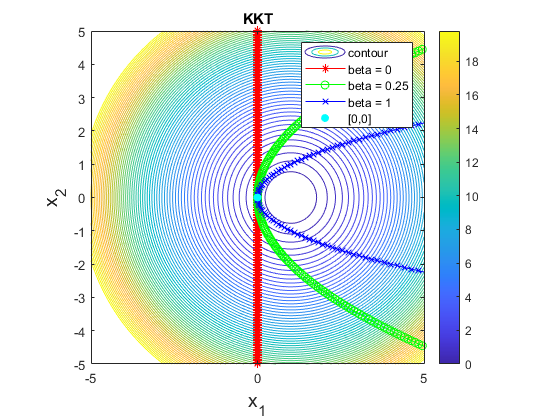

figure
[C,h] = contour(X,Y,funObj(X,Y),v);
colorbar, axis image,
hold on
plot(x_1(x_2,0),x_2,'r-*')
hold on
plot(x_1(x_2,0.25),x_2,'g-o')
hold on
plot(x_1(x_2,1),x_2,'b-x')
hold on
scatter([0],[0],'cyan',"filled")
xlim([-5,5])
xlabel('x_1','fontsize',14)
ylabel('x_2','fontsize',14)
legend('contour','beta = 0','beta = 0.25','beta = 1','[0,0]')
title('KKT')

### Question three:

- For β = 1, [0,0] is no longer a minimizer and it is not a maximizer neither.

- The minimizer would be the closet to the innermost centric circle in picture.

## Four: A regularized least-squares problem

### Question one:

- A = [a1'; a2' ... ; ak'], an "k x n" matrix

- L = [-1 1 0........; 0 -1 1 0 ...; 0 0 -1 1 ...; ...; 0 ... -1 1], an "(n-1) x n" matrix

### Question two:1

- A' = [A; sqrt(δ)*L]

- b' = [b; zeros]

- transpose(A')*A'*x = transpose(A')*b'

### Question three:

clear all;
var = load('vec_b (1).mat');
b = var.b;
n = length(b);
[A, L] = get_AL(n);
Ashape = size(A)

Ashape =        16384       16384


Lshape = size(L)

Lshape =        32768       16384


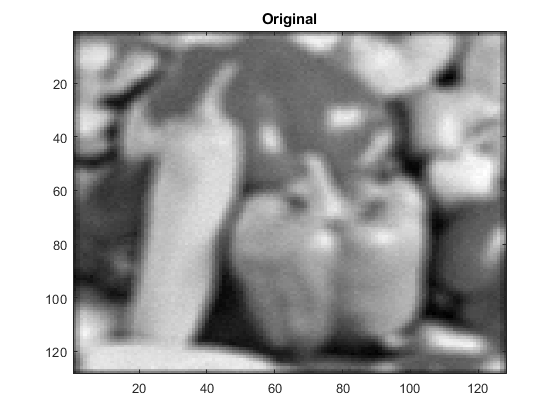

figure, imagesc(reshape(b,sqrt(n),sqrt(n))),
colormap(gray)
title('Original')

### Question four:

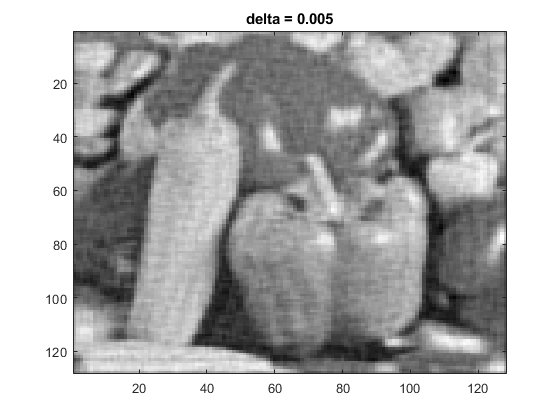

delta = 0.005;
A_ = [A; sqrt(delta)*L];
b_ = [b; zeros(Lshape(1),1)];
x = (A_'*A_)\(A_'*b_);
figure, imagesc(reshape(x,sqrt(n),sqrt(n))),
colormap(gray)
title('delta = 0.005')

### Question five:

- Observation: We can see that the when δ gets larger, the image gets blurred again. The image looks much "smoother".

- Explanation: the δ represents the penalty which stands for how much close or similar two adjacent pixel values are. The larger the parameter is, the heavier the smoothness occupies in the objective target. Therefore, the output will have unclear boundaries. (The pepper edges start to be very unclear)

deltas = [1e-7, 0.0001, 0.4, 10]

deltas =     0.0000    0.0001    0.4000   10.0000


delta: 


delta = 1.0000e-07

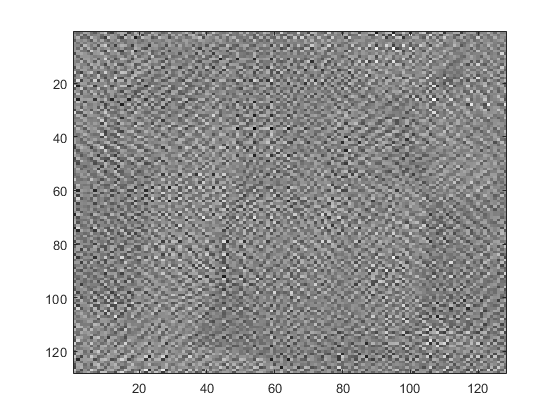

delta: 


delta = 1.0000e-04

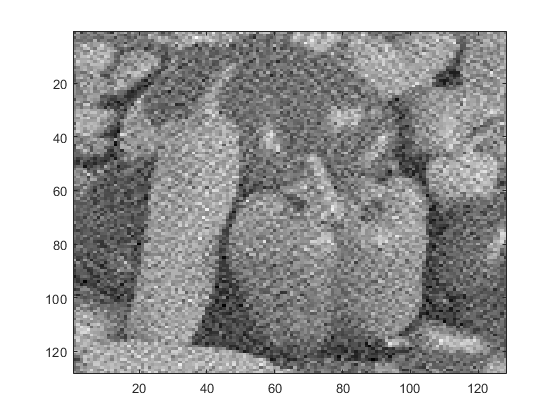

delta: 


delta = 0.4000

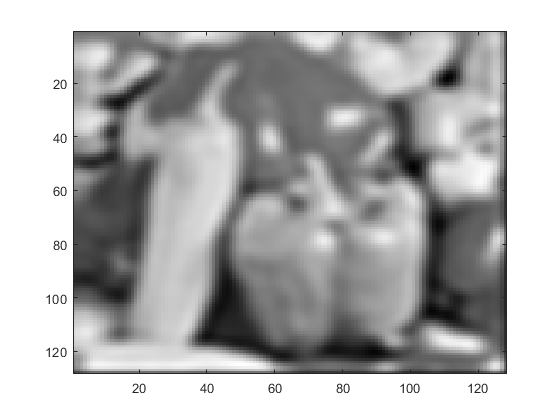

delta: 


delta = 10

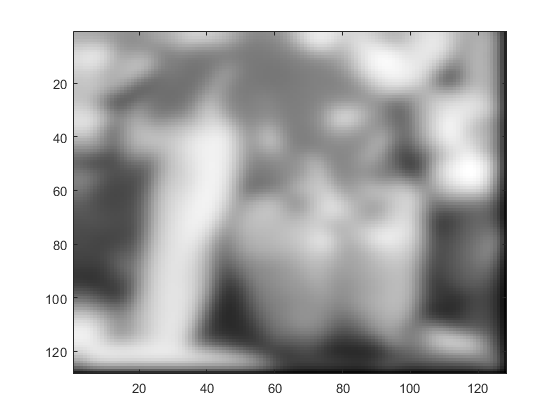

for i = 1:length(deltas)
    disp("delta: ")
    delta = deltas(i)
    A_ = [A; sqrt(delta)*L];
    b_ = [b; zeros(Lshape(1),1)];
    x = (A_'*A_)\(A_'*b_);
    figure, imagesc(reshape(x,sqrt(n),sqrt(n))),
    colormap(gray)
end